# Magnetic field of a current loop from [Biot-Savart](https://de.wikipedia.org/wiki/Biot-Savart-Gesetz)  


$$\mathbf B(\mathbf r)=
\frac {\mu_0 I}{4\pi }
\oint \frac{d \mathbf s \times (\mathbf r-\mathbf s) }{|\mathbf r-\mathbf s|^3}

$$


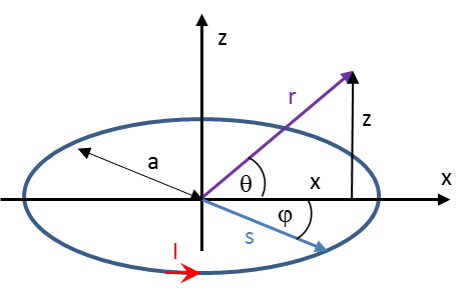

Due to symmetry it is sufficient to consider xz-plane (y=0) only

The x-component thus corresponds to the radial component r and the y-component to the azimuthal component phi.

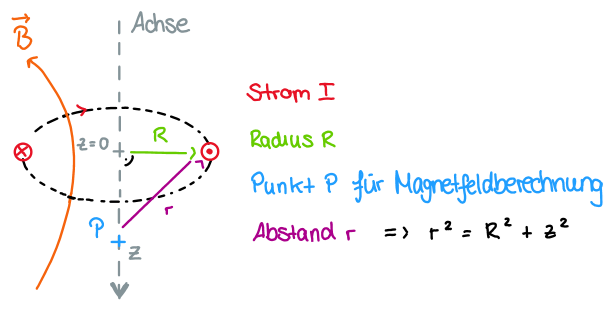

## symbolic solution

clear,clc
syms phi a x I positive
syms z y real

rv=[x,0,z]';                 % position vector of magnetic field (plane y=0)
sv=a*[cos(phi),sin(phi),0]'; % position vector of current (plane z=0)

Substitution of the integration variable: ds$\to$$d\varphi$: ds = $\frac{\textrm{ds}}{d\varphi }\ldotp d\varphi$

ds=diff(sv,phi)              % current vector ds 

$$ds = \left(\begin{array}{c} -a\,\sin\left(\varphi \right)\\ a\,\cos\left(\varphi \right)\\ 0 \end{array}\right)$$

visualize current vector ds

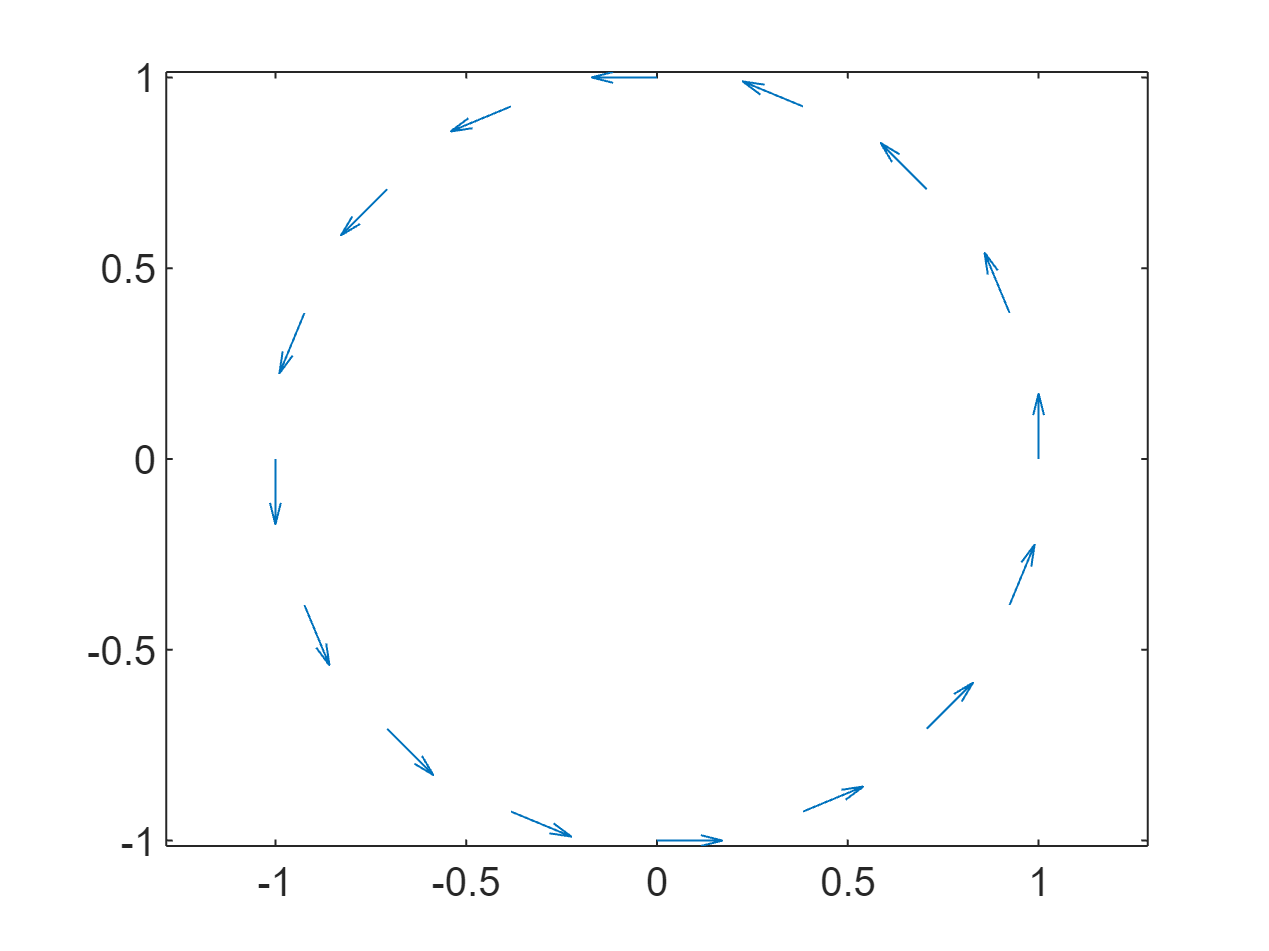

p=0:pi/8:2*pi;quiver(cos(p),sin(p),-sin(p),cos(p),.25),axis equal

[Biot-Savart](https://de.wikipedia.org/wiki/Biot-Savart-Gesetz)           $\mathbf H(\mathbf r)=
\frac { I}{4\pi }
\oint \frac{d \mathbf s \times (\mathbf r-\mathbf s) }{|\mathbf r-\mathbf s|^3}

$

dH=I/(4*pi)*cross(ds, rv-sv)/norm(rv-sv)^3;
% norm(rv-sv) = |rv-sv|

This integral matlab cannot solve symbolically 

%int(dH,phi,0,2*pi)

if we restrict ourselves to the magnetic field on the axis (x=0), matlab finds the solution

dH0=simplify(subs(dH,x,0));
Hz0(z)=int(dH0,phi,0,2*pi)

$$Hz0(z) = \left(\begin{array}{c} 0\\ 0\\ \frac{\text{I}\,a^{2}}{2\,{\left(a^{2}+z^{2}\right)}^{3/2}} \end{array}\right)$$

the magnetic field at the center of the loop can be simplified even further

Hz0r0=subs(Hz0,z,0)

$$Hz0r0(z) = \left(\begin{array}{c} 0\\ 0\\ \frac{\text{I}}{2\,a} \end{array}\right)$$

## numeric solution

dHn = matlabFunction(dH);

to use integral() all parameters but one (phi) have to be fixed

I=1;    % current
a=1;    % radius of loop
x=0;    % field location: radial distance of loop center
z=1;    % field location: axial distance of loop center

dHn=@(phi) dHn(I,a,phi,x,z);

numeric solution of magentic field needs option ('ArrayValued',true) as dHn is a vector

H=integral(dHn,0,2*pi,'ArrayValued',true)

H =    -0.0000
   -0.0000
    0.1768


for comparison symbolic solution from above

eval(Hz0(z))

ans =          0
         0
    0.1768
